# The Penny Myth

*Original Author:* Allen Downey

*Updated by:* Stephanos Matsumoto and Zachary del Rosario (Fall 2020)

Learning outcomes: As a result of working through this notebook, you will learn:

- The basic process to physical modeling: Posing a question, building a model, checking the model, answering the question

- The basics of using a Matlab Live Script

You might have heard that a penny dropped from the top of the Empire State Building would be going so fast when it hit the pavement that it would be embedded in the concrete; or if it hit a person, it would break their skull. We'll probe this myth by building a model and using it to study the penny drop scenario. Let's be clear about the question we're trying to answer:

**Question:** If one were to drop a penny from the top of the Empire State Building, would it reach a speed large enough to be dangerous?

## Model 1: Gravity with no air resistance

If air resistance is negligible, the primary force acting on the penny is gravity, which causes the penny to accelerate downward. In terms of a free body diagram, Model 1 looks like this:

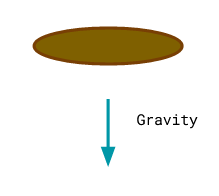

For a mathematical treatment, we start from Newton's Second law


$$F_{\text{total}} = m \frac{d^2 h}{dt^2}$$


where $a = \frac{d^2h}{dt^2}$ is the vertical acceleration and $m$ is the mass of the penny. In line with our free body diagram above, let's assume the only external force is gravity 

$F_{\text{total}} = F_{\text{gravity}} = mg$. 

Combining these expressions reduces to $\frac{d^2h}{dt^2} = g$. 

### Defining the model

The expression $\frac{d^2h}{dt^2} = g$ is not the full model; we also need to specify two other quantities before we'll have a fully-defined model we can *solve *to compute numbers. Those two other quantities are the initial conditions: for this model those are the initial height fallen $h_0$ (which we'll set to zero), and the initial velocity $v_0$ (we'll assume the penny is dropped, not thrown, so we'll set this to zero as well).


$$\frac{d^2h}{dt^2} = g \\
v(t=0) = v_0 = 0 \\
h(t=0) = h_0 = 0$$


This set of expressions is a full model that we can solve.

### Solving the model

Solving the model above is not hard, but you may not have seen this kind of math before. That's ok! We'll learn how to solve this kind of model through this class.

Using techniques to solve an *ordinary differential equation* (ODE), we can solve for the velocity $v$ and height fallen $h$ at any given time $t$. These expressions are:


$$v = g t \\
h = \frac{1}{2}gt^2$$


However, we don't yet know the time it will take for the penny to fall a given distance; to figure this out we'll need to solve for $t$. Solving the $h$ expression for $t$ we find


$$t = \sqrt{2h/g}$$


Let's plug in some numbers to connect the model to the specific scenario we want to study. To do that, we'll make use of Matlab through a *Live Script.*

### Working in a Matlab Live Script

This document is a Matlab Live Script: Essentially it's running computer code along with the text you see here. *Think of a Live Script as a modern lab notebook:* In a Live Script you can write computer code to run simulations, and you can write text to remind yourself why you did what you did. We'll make thorough use of Live Scripts in this class, so it's worth getting a bit of orientation.

We can treat Matlab as a *fancy calculator* to help keep track of our calculations. The following two lines of computer code store numbers in *variables*; below we set variables `g, h`. The grey zone below means the text is computer code (not "plain text") that can be *executed*.

g = 9.8 % Acceleration due to gravity (m / s^2)

g = 9.8000

h = 381 % Height of the Empire State Building (m)

h = 381

**Exercise:** Click inside this section (it should be bounded by a thin blue rectangle once selected) and press `Control + Enter`; this will *execute* the code above. You should see values assigned to the variables `g, h` in the right panel. This will let you know the code executed correctly!

The syntax `x = 1` assigns the value `1` to the variable `x`. We can use variables to store values for later computations, as we'll see below.

### Fundamental operations

We can carry out fundamental operations with Matlab, just like we might with a calculator. Since we stored values in `g, h` above, we can now carry out calculations with those values. The following code chunk demonstrates just a few of the operations we can do in Matlab:

% Addition
g + h

ans = 390.8000

% Subtraction
g - h

ans = -371.2000

% Multiplication
g * h

ans = 3.7338e+03

% Division
g / h

ans = 0.0257

% Exponentiation
g ^ 2

ans = 96.0400

% Math functions
sqrt(g)

ans = 3.1305

**Exercise:** Using Matlab code to implement the mathematical statements above, compute the time $t$ it takes for the penny to fall, and the velocity of the penny $v$ when it hits the ground. How does this model result relate to the **question** we're trying to answer?

*Hint*: Remember that `v` will be in units of meters per second. You can multiply by about `2.2` to convert meters per second to miles per hour.

% TODO: Compute t and v
t = 1 % Replace 1 with the correct expression!

t = 1

v_model1 = 1 % Replace 1 with the correct expression!

v_model1 = 1

## Bring in the data!

We can bring in some data to test our model. First let's make sure the model reflects one of the facts we *know *it should get right: We computed the fall time `t` such that the height `h` at that time would be that of the Empire State Building. Does the penny fall that distance in the correct time?

*Note:* There's no need to modify the following code; you'll learn how to do all of this through the class!

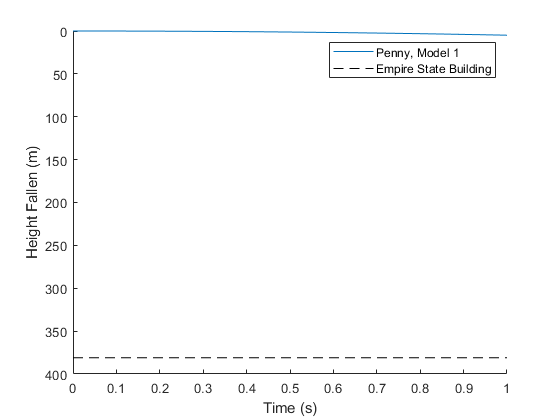

% Create a vector of several points in time
T = linspace(0, t);
% Evaluate the model at several points in time
H_model1 = 0.5 * g * T.^2;

% Plot the data
figure(1); clf; hold on;

plot(T, H_model1); label1 = "Penny, Model 1";
plot([T(1), T(end)], [h, h], "k--"); label2 = "Empire State Building";

xlabel("Time (s)");
ylabel("Height Fallen (m)"); set(gca, 'YDir','reverse'); 
legend({label1, label2}, 'Location', 'NorthEast');

Note that the penny reaches the correct height at the correct time. So at least the model is *internally consistent*.

Now here's another piece of data: A falling penny tends to reach a maximum velocity, called *terminal velocity*, then stop accelerating. The next exercise will have you compare the model results against this observed terminal velocity.

**Exercise:** Compute the velocity of the penny at each point in time, based on Model 1. The code below will plot your calculated values. Does the model exhibit a terminal velocity like real pennies? What is our model missing? How do these results relate to the trustworthiness of the model for answering our **question**?

*Hint:* You can use the code above as a hint as to how to do this.

% TODO: Replace `1` with the correct expression
V_model1 = 1;


The following code will plot your results:

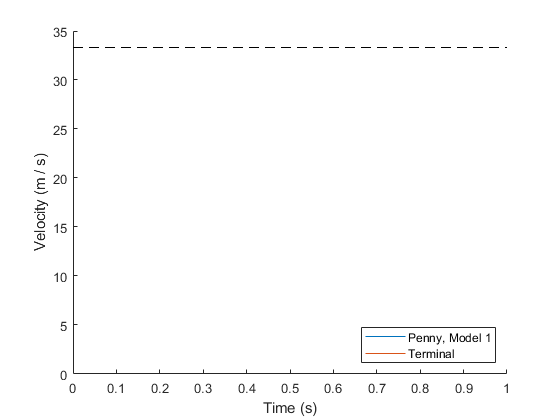

% NOTE: No need to edit this!
% Terminal velocity, asserted but not necessarily "correct"
v_t_asserted = 73.3 / 2.2; % Penny terminal velocity (m / s)

% Plot the data
figure(2); clf; hold on;

plot(T, V_model1); label1 = "Penny, Model 1";
plot([T(1), T(end)], [v_t_asserted, v_t_asserted], "k--"); label2 = "Terminal";

xlabel("Time (s)");
ylabel("Velocity (m / s)");
legend({label1, label2}, 'Location', 'SouthEast');

Does the model exhibit a terminal velocity like real pennies? What is our model missing? How do these results relate to the trustworthiness of the model for answering our **question**?

## Model 2: Gravity opposed by air resistance

Model 1 would be appropriate if the penny were falling through a vacuum, but the Empire State Building is surrounded by atmosphere. Those gasses resist motion since air molecules bounce against moving objects, creating a resistive force called *air resistance*. Returning to a free body diagram of the penny, Model 2 looks like this:

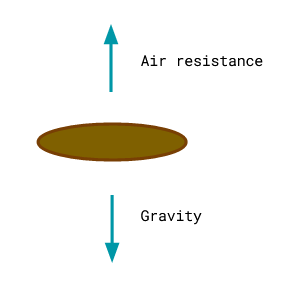

Now we have a different total force


$$F_{\text{total}} = F_{\text{gravity}} - F_{\text{air resistance}}$$


We modeled $F_{\text{gravity}} = mg$ before, and we'll continue to use this assumption. However, we need some way to model the air resistance.

### Defining the model

Air resistance is often modeled with the [drag equation](https://en.wikipedia.org/wiki/Drag_equation)


$$F_{\text{air resistance}} = q A C_D$$


where

$q = \frac{1}{2} \rho_{\text{air}} v^2$ is the *dynamic pressure*, $A$ is the *reference area* of the object moving through air, and $C_D$ is the *drag coefficient* of the object. Note that air resistance now depends on the velocity $v$ of the projectile---this makes it harder to solve for the motion of the penny. However, remember that our **question** is just about the speed when the penny reaches the ground. Therefore, we only need to get the terminal velocity from the model.

Conceptually, the air resistance will increase with velocity, and velocity will increase so long as gravity overcomes air resistance. However, once air resistance equals the force of gravity, the penny will stop accelerating---at that point it reaches terminal velocity. The following plot shows these two forces schematically: Terminal velocity is the point where the two curves intersect.

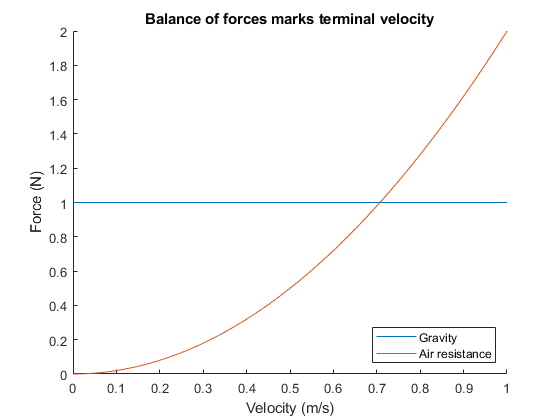

% NOTE: Here's a schematic view of the opposing forces, using some rough numbers
m_ex = 1 / g; % mass to make F_{gravity} come out to 1 (kg)
rho_ex = 1.225; % Density of air at sea level, 15 C (kg / m^3)
Cd_ex = 4 / rho_ex;
A_ex = 1.0;
v_sweep = linspace(0, 1);

% Compute forces
F_gravity_ex = m_ex * g;
F_drag_ex = (0.5 * rho_ex * v_sweep.^2) * Cd_ex * A_ex;

% Plot
figure(3); clf; hold on;
plot([v_sweep(1), v_sweep(end)], [1, 1]); label1 = "Gravity";
plot(v_sweep, F_drag_ex); label2 = "Air resistance";
xlabel("Velocity (m/s)");
ylabel("Force (N)");
legend({label1, label2}, 'Location', 'SouthEast');
title("Balance of forces marks terminal velocity")

Thus, to get the answer we need out of Model 2, we need only find the intersection between these two curves.

### Solving the model

When the air resistance $F_{\text{air resistance}}$ equals the force of gravity $F_{\text{gravity}}$, the following equation holds


$$mg = \frac{1}{2} \rho_{\text{air}} v^2 A C_D$$


Solving for $v$, we find an expression for the terminal velocity


$$v_t = \sqrt{\frac{2mg}{A C_D}}$$


Now we need to find values for all the terms on the right hand side of the equation for $v_t$.

### Running the numbers

To start, let's try using the model at a single set of values. I did some quick Google searching for "reasonable" values relating to our problem, which are written below.

% Provided
m = 2.5 * 0.001; % Mass of a penny; 2.5 g = .0025 kg
rho_air = 1.225; % Density of dry air at sea level and 15 C; kg / m^3
C_D = 0.1; % Drag coefficient, assumed; unitless
diameter = 19.05 * 0.001; % Diameter of a penny; 19.05 mm = .01905 m
% Derived
A = pi * (diameter / 2)^2

A = 2.8502e-04

**Exercise:** Complete the calculation of the terminal velocity. How does your calculated value compare with the `v_t_asserted` value asserted above?

v_t_asserted % Show the asserted terminal velocity

v_t_asserted = 33.3182

v_t_calc = 1 % TODO: Replace 1 with the correct expression

v_t_calc = 1

### Sweeping the numbers

A model is only as good as the assumptions it uses; if our assumptions are bad then our results will be bad (this is sometimes called "garbage in, garbage out"). Here are some uncertainties associated with all of the numbers that enter into the Model 2 solution for $v_t$:

- $m = 2.5$ grams is for a typical penny; there could be manufacturing variation in this value.

- Similarly $d = 19.05$ mm is for a typical penny; there could be manufacturing variation.

- Furthermore the penny is *not guaranteed to lie flat* as it is falling! This could change the "effective diameter" it presents to the wind, leading to a smaller $A$ for the calculation. If the penny is at an angle, the "effective diameter" it presents to the wind will be smaller than its true diameter.

- Drag coefficients $C_D$ tend to run between 0.1 (for well-designed aircraft wings) up to 1.0 (for rather non-aerodynamic shapes, like a brick). It's not clear what the $C_D$ for a penny should be.

To capture this range of possibilities, we'll carry out a *parameter sweep*. That is, we'll re-run the model at a variety of different parameter values, and study the range of values we observe. Thus, instead of getting one single value out of our model, we'll get a range of values that could plausibly occur.

**Exercise:** Do some reading & thinking, and come up with your own *plausible* bounds for the drag coefficient $C_D$ and "effective diameter" $d_e$. Compare your bounds on $v_t$ with the single value you found from Model 1.

*Hints:*

- You may find [this article](https://en.wikipedia.org/wiki/Drag_coefficient) on the drag coefficient useful for determining plausible bounds.

- Think about the different angles the penny could make with the direction it is falling, and use that knowledge to set reasonable bounds for $d_e$

% TODO: define your own bounds
C_D_lo = 0.1; % Pick a lower bound for drag coefficients
C_D_hi = 0.1; % Pick an upper bound for drag coefficients

d_e_lo = 0.01905; % Pick a lower bound for an "effective" diameter
d_e_hi = 0.01905; % Pick an upper bound for an "effective" diameter

% NOTE: No need to edit this code; this just takes your choices and puts
% them in `vectors` (which you'll learn about in the Robot Book!)
C_D_bounds = [C_D_lo, C_D_hi];
d_e_bounds = [d_e_lo, d_e_hi];

The following code will compute the lowest and highest $v_t$ over your bounds.

% NOTE: The following code will find the minimum and maximum values of v_t
% over the range of values you defined above.
v_t_lo = v_t_calc;
v_t_hi = v_t_calc;
for c_d = C_D_bounds
    for d = d_e_bounds
        % Compute v_t under assumed values
        A_tmp = (d / 2)^2 * pi;
        v_t_tmp = sqrt(2 * m * g / (A_tmp * c_d));
        % Record min and max
        v_t_lo = min(v_t_tmp, v_t_lo);
        v_t_hi = max(v_t_tmp, v_t_hi);
    end
end
% Report the resulting bounds on v_t
[v_t_lo, v_t_hi]

ans =     1.0000   41.4628


## How Fast is Too Fast?

We've spent a lot of time computing speeds of pennies, but there's an important limitation to this analysis: **Our models don't tell us anything about how dangerous penny speeds are to humans!** To fully answer our question, we need to connect speed to some notion of danger.

The Mythbusters tested the idea of the [Penny Drop](https://www.youtube.com/watch?v=PHxvMLoKRWg) in Season 1, Episode 4. They tested shooting a penny at a human surrogate made of ballistics gel and a (hopefully fake?) skull at **~65 miles per hour**. At that speed they found the penny would not harm a human. (In fact, they later shot Adam [in the butt](https://ew.com/article/2016/03/02/stephen-colbert-mythbusters-adam-savage/) with a penny. He lived.)

% Mythbusters-determined survivable velocity
v_survivable = 65 / 2.2 % in m / s

v_survivable = 29.5455

% Model 1 results
v_model1

v_model1 = 1

% Model 2 bounds
[v_t_lo, v_t_hi]

ans =     1.0000   41.4628


**Exercise:** Answer the following questions:

- How do the model results compare with the Mythbusters-tested velocity?

- Do you think the Mythbusters velocity is the *upper limit* of penny impact velocity a human could survive?

- Based on your model results and Mythbusters' survivable velocity, can you *confidently conclude* that a falling penny would not harm a human? If not, what additional information would you need to make a confident conclusion?